clearvars; close all;
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

N_IDEALITY_FACTOR = 2.09;
N_IDEALITY_FACTOR_STD = 0.02;
conv = 50e3; %Ohm

% Import
LPath = 'D:\Profile\qse\Files\_EDMRoC pinSC\IV curve\IV curve chip\01_IV_curve_chip_spento.txt';
ivdata = importdata(LPath, '\t', 1);
V = ivdata.data(:,1);
I = ivdata.data(:,2)/conv;
I = (I + abs(I(V == 0))); % A
I(V == 0)

ans = 0

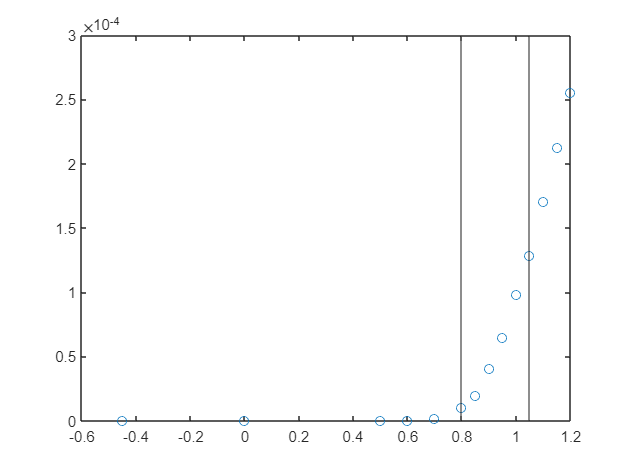

nI = numel(I);
figure()
plot(V, I, 'o')
xline(V(6)) %idxStartStart
xline(V(11))

# Fit in the forward bias region

## Calculate the x y pairs

nStart = 6;
IDX_START_IN = 6;
IDX_START_FIN = IDX_START_IN + nStart - 1;
linModel = @(x, p) p(1)*x + p(2);

Varying the initial value of i0 between IDX_START_IN and IDS_START_FIN. For each idxStart perform the complete algorithm and in the end compare the results.

for idxStart = IDX_START_IN:IDX_START_FIN
    ny = (nI - idxStart + 1)*(nI - idxStart)/2
    [x, y] = deal(zeros(ny, 1)); 
    iy = 1;
    for i0 = idxStart:nI - 1
        I0 = I(i0);
        V0 = V(i0);
        for ii = i0 + 1:nI
            y(iy) = log(I(ii)/I0)/(I(ii)-I0);
            x(iy) = (V(ii)-V0)/(I(ii)-I0);
            iy = iy + 1;
        end
    end

## Ectract $\alpha \;$and $R_s$


$$y=\alpha \;\left(-R_S +x\right)=\alpha \;x-R_{S\;} \alpha \;$$
 

    p0 = [19, -2e4]; vary = [5, 2e4];
    ii = idxStart - IDX_START_IN + 1; % Index for the result arrays
%     figure()
%     plot(x, y, 'o')
%     hold on
%     plot(x, linModel(x, p0))
    FitOpt.x = x;   % Necessary because (x y) pairs are not increasingly ordered
    X = [x ones(size(x))];
    param = X \y;
    disp(fprintf("==============\n==============\n==============\nidxStrart = %i\n==============\n==============\n==============", idxStart))
    Fit1{ii} = esfit(y, @(p) linModel(x, p), p0, vary, FitOpt);

    xDummy = linspace(min(x), max(x), 1000);
    figure()
    plot(x, y, 'o')
    hold on
    plot(xDummy, Fit1{ii}.scale*Fit1{ii}.pfit(1)*xDummy + Fit1{ii}.scale*Fit1{ii}.pfit(2))
    xlim(setAxLim(x, 0.1))
    ylim(setAxLim(y, 0.1))

## Extract Is


$$\ln \left(I\right)=\ln \left(I_{\textrm{s1}} \right)+\alpha_1 \left(V-I*R_s \right)$$


    Rs_ = -Fit1{ii}.pfit(2)/Fit1{ii}.pfit(1);
    Vc = V(idxStart:end) - I(idxStart:end)*Rs_; % Corrected voltage values
    lnI = log(I(idxStart:end));

    p0 = [18.8, -30]; vary = [18, 100];
    Fit2{ii} = esfit(lnI,@(p) linModel(Vc, p), p0, vary);
    
    xDummy = linspace(min(Vc), max(Vc), 1000);
    figure()
    plot(Vc, lnI, 'o')
    hold on
    plot(xDummy, Fit2{ii}.scale*Fit2{ii}.pfit(1)*xDummy + Fit2{ii}.scale*Fit2{ii}.pfit(2))
    xlim(setAxLim(Vc, 0.1))
    ylim(setAxLim(lnI, 0.1))

## Extract $R_{\mathrm{sh}}$

I am not extracting $R_{\textrm{sh}}$ because there aren't enough datapoints in the around the short circuit point.

ny = 36

idxStrart = 6
==============   103



-- esfit ------------------------------------------------
Data size:                [36, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.07672e+03   edge 1.00000e-01   initial simplex
iteration   2: value 2.07672e+03   edge 4.00000e+03   reflection
iteration   3: value 2.07672e+03   edge 2.00000e+03   contraction inside
iteration   4: value 2.07672e+03   edge 1.00000e+03   contraction inside
iteration   5: value 2.07672e+03   edge 1.00000e+03   contraction inside
iteration   6: value 2.07672e+03   edge 1.00000e+03   contraction inside
iteration   7: value 2.07499e+03   edge 5.93750e+02   contraction inside
iteration   8: value 2.07499e+03   edge 5.93750e+02   reflection
iteration   9: value 2.07484e+03   edge 3.

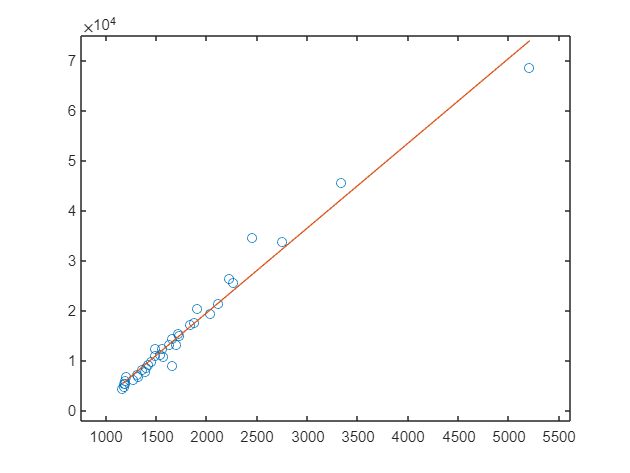

-- esfit ------------------------------------------------
Data size:                [9, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.00860e-01   edge 1.00000e-01   initial simplex
iteration   2: value 2.00860e-01   edge 1.00000e+01   contraction outside
iteration   3: value 2.00860e-01   edge 5.00000e+00   contraction inside
iteration   4: value 6.33283e-02   edge 3.75000e+00   contraction inside
iteration   5: value 6.33283e-02   edge 5.00000e+00   reflection
iteration   6: value 6.33283e-02   edge 5.00000e+00   contraction inside
iteration   7: value 6.33283e-02   edge 2.96875e+00   contraction inside
iteration   8: value 6.33283e-02   edge 2.96875e+00   contraction inside
iteration   9: value 6.22436e-02 

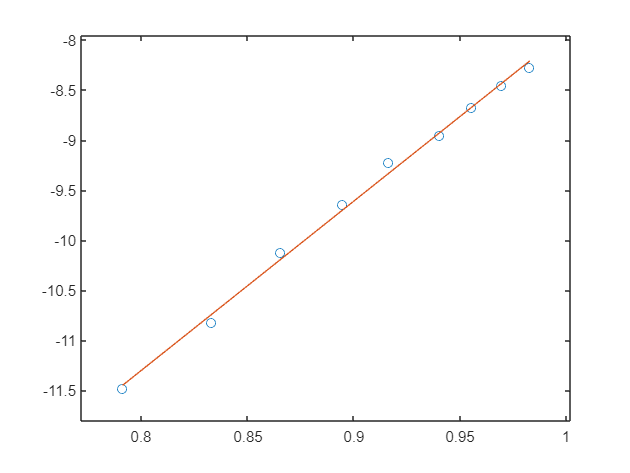

ny = 28

idxStrart = 7
==============   103



-- esfit ------------------------------------------------
Data size:                [28, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.61380e+03   edge 1.00000e-01   initial simplex
iteration   2: value 1.61380e+03   edge 2.00000e+03   contraction inside
iteration   3: value 1.61380e+03   edge 2.00000e+03   contraction outside
iteration   4: value 1.61380e+03   edge 2.00000e+03   reflection
iteration   5: value 1.59093e+03   edge 1.12500e+03   contraction inside
iteration   6: value 1.59093e+03   edge 1.12500e+03   reflection
iteration   7: value 1.59093e+03   edge 6.87500e+02   contraction inside
iteration   8: value 1.59093e+03   edge 6.87500e+02   contraction inside
iteration   9: value 1.59053e+03   edge 4

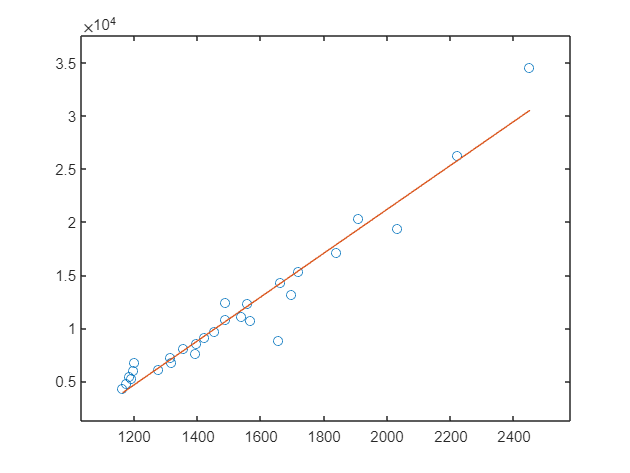

-- esfit ------------------------------------------------
Data size:                [8, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 5.66074e-02   edge 1.00000e-01   initial simplex
iteration   2: value 5.66074e-02   edge 1.00000e+01   contraction outside
iteration   3: value 5.66074e-02   edge 5.00000e+00   contraction inside
iteration   4: value 5.66074e-02   edge 5.00000e+00   reflection
iteration   5: value 5.66074e-02   edge 5.00000e+00   contraction inside
iteration   6: value 5.66074e-02   edge 2.36250e+00   contraction outside
iteration   7: value 5.66074e-02   edge 2.81250e+00   reflection
iteration   8: value 5.66074e-02   edge 2.81250e+00   contraction inside
iteration   9: value 5.66074e-02   edge 

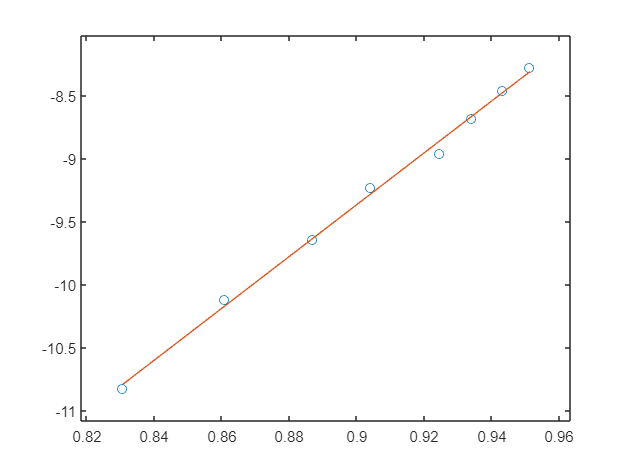

ny = 21

idxStrart = 8
==============   103



-- esfit ------------------------------------------------
Data size:                [21, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.15868e+03   edge 1.00000e-01   initial simplex
iteration   2: value 1.15868e+03   edge 4.00000e+03   reflection
iteration   3: value 1.15868e+03   edge 2.00000e+03   contraction outside
iteration   4: value 1.15611e+03   edge 1.00000e+03   contraction outside
iteration   5: value 1.15611e+03   edge 1.00000e+03   contraction inside
iteration   6: value 1.15611e+03   edge 1.00000e+03   contraction outside
iteration   7: value 1.15526e+03   edge 5.93750e+02   contraction inside
iteration   8: value 1.15526e+03   edge 5.93750e+02   reflection
iteration   9: value 1.15516e+03   edge

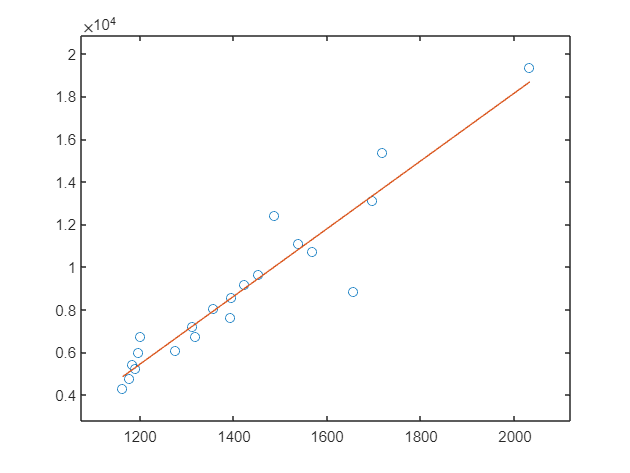

-- esfit ------------------------------------------------
Data size:                [7, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 9.47130e-02   edge 1.00000e-01   initial simplex
iteration   2: value 9.47130e-02   edge 1.00000e+01   contraction outside
iteration   3: value 4.46539e-02   edge 7.50000e+00   contraction inside
iteration   4: value 4.46539e-02   edge 3.12500e+00   contraction inside
iteration   5: value 4.23282e-02   edge 3.43750e+00   contraction outside
iteration   6: value 4.23282e-02   edge 3.43750e+00   contraction inside
iteration   7: value 3.90312e-02   edge 1.91406e+00   contraction outside
iteration   8: value 3.46407e-02   edge 2.19727e+00   contraction inside
iteration   9: value 3.

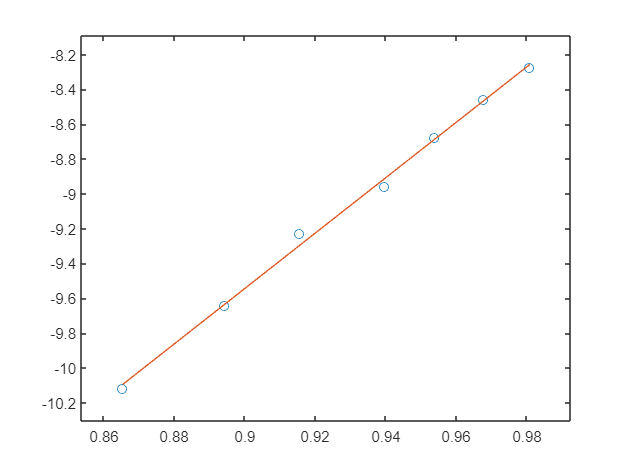

ny = 15

idxStrart = 9
==============   103



-- esfit ------------------------------------------------
Data size:                [15, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.21708e+03   edge 1.00000e-01   initial simplex
iteration   2: value 1.17365e+03   edge 6.00000e+03   expansion
iteration   3: value 1.17365e+03   edge 2.00000e+03   contraction outside
iteration   4: value 1.16184e+03   edge 2.12500e+03   contraction inside
iteration   5: value 1.16184e+03   edge 1.50000e+03   reflection
iteration   6: value 1.16184e+03   edge 1.50000e+03   contraction inside
iteration   7: value 1.16184e+03   edge 7.65625e+02   contraction inside
iteration   8: value 1.16184e+03   edge 3.98438e+02   contraction inside
iteration   9: value 1.16178e+03   edge 2.

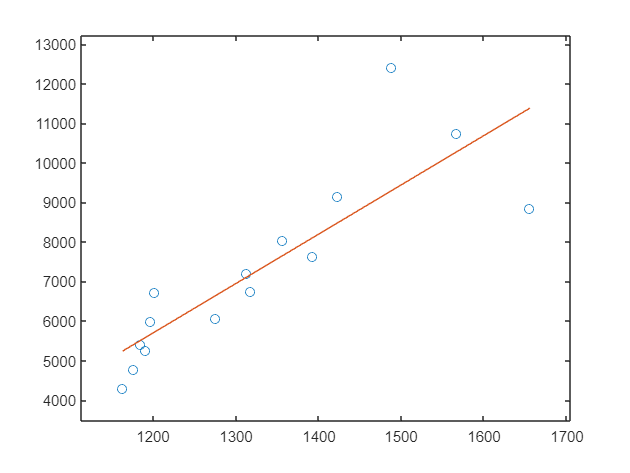

-- esfit ------------------------------------------------
Data size:                [6, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 6.56901e-02   edge 1.00000e-01   initial simplex
iteration   2: value 6.56901e-02   edge 2.00000e+01   reflection
iteration   3: value 6.56901e-02   edge 2.00000e+01   contraction outside
iteration   4: value 4.66757e-02   edge 1.50000e+01   reflection
iteration   5: value 4.66757e-02   edge 6.25000e+00   contraction inside
iteration   6: value 4.66757e-02   edge 5.00000e+00   contraction inside
iteration   7: value 3.89601e-02   edge 4.68750e+00   contraction inside
iteration   8: value 3.89601e-02   edge 5.00000e+00   reflection
iteration   9: value 3.55035e-02   edge 3.59375e+

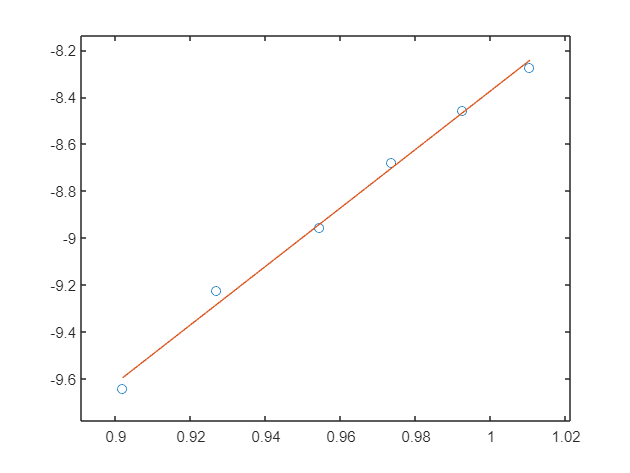

ny = 10

idxStrart = 10
==============   104



-- esfit ------------------------------------------------
Data size:                [10, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.03116e+03   edge 1.00000e-01   initial simplex
iteration   2: value 6.70628e+02   edge 6.00000e+03   expansion
iteration   3: value 5.81776e+02   edge 6.00000e+03   reflection
iteration   4: value 5.81776e+02   edge 4.00000e+03   reflection
iteration   5: value 5.81776e+02   edge 3.50000e+03   contraction outside
iteration   6: value 5.81776e+02   edge 2.00000e+03   reflection
iteration   7: value 5.81776e+02   edge 1.50000e+03   contraction inside
iteration   8: value 5.81776e+02   edge 6.25000e+02   contraction inside
iteration   9: value 5.81776e+02   edge 5.93750e+02   cont

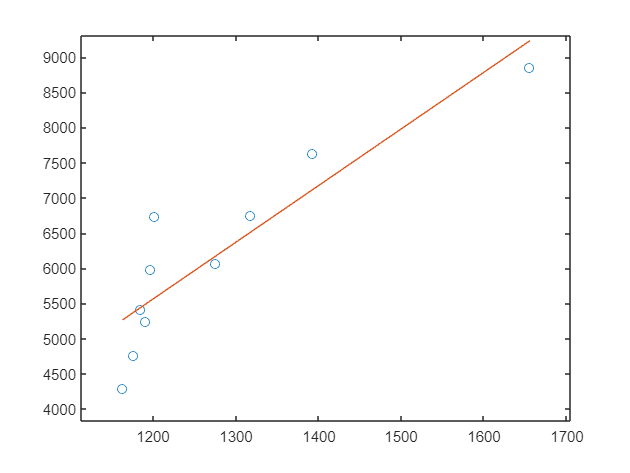

-- esfit ------------------------------------------------
Data size:                [5, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.89563e-01   edge 1.00000e-01   initial simplex
iteration   2: value 4.42828e-02   edge 2.00000e+01   reflection
iteration   3: value 4.42828e-02   edge 2.00000e+01   reflection
iteration   4: value 4.42828e-02   edge 1.00000e+01   contraction outside
iteration   5: value 2.91329e-02   edge 1.00000e+01   reflection
iteration   6: value 2.91329e-02   edge 1.00000e+01   contraction inside
iteration   7: value 2.91329e-02   edge 1.00000e+01   contraction outside
iteration   8: value 2.42947e-02   edge 5.93750e+00   contraction inside
iteration   9: value 2.42947e-02   edge 5.93750e

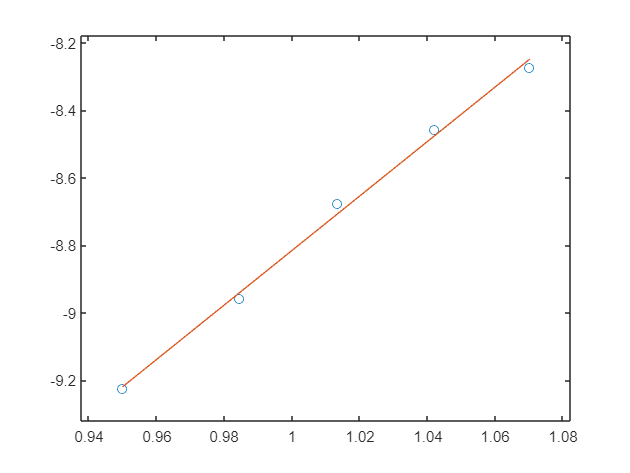

ny = 6

idxStrart = 11
==============   104



-- esfit ------------------------------------------------
Data size:                [6, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 3.40430e+02   edge 1.00000e-01   initial simplex
iteration   2: value 3.40430e+02   edge 2.00000e+03   contraction inside
iteration   3: value 3.40430e+02   edge 2.00000e+03   reflection
iteration   4: value 3.40430e+02   edge 2.00000e+03   contraction inside
iteration   5: value 3.14626e+02   edge 1.25000e+03   contraction inside
iteration   6: value 2.61205e+02   edge 1.18750e+03   contraction inside
iteration   7: value 2.57865e+02   edge 1.18750e+03   reflection
iteration   8: value 2.57865e+02   edge 7.81250e+02   contraction inside
iteration   9: value 2.57865e+02   edge 7.5

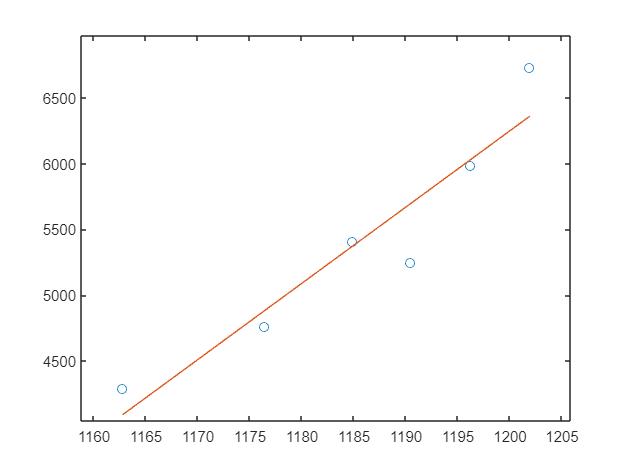

-- esfit ------------------------------------------------
Data size:                [4, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.66151e-01   edge 1.00000e-01   initial simplex
iteration   2: value 1.66151e-01   edge 1.00000e+01   contraction outside
iteration   3: value 1.25099e-01   edge 1.00000e+01   reflection
iteration   4: value 1.25099e-01   edge 1.00000e+01   contraction inside
iteration   5: value 1.25099e-01   edge 1.00000e+01   reflection
iteration   6: value 1.13719e-01   edge 5.62500e+00   contraction inside
iteration   7: value 1.13719e-01   edge 5.62500e+00   reflection
iteration   8: value 5.65839e-02   edge 3.43750e+00   contraction inside
iteration   9: value 2.38546e-02   edge 4.14844e+

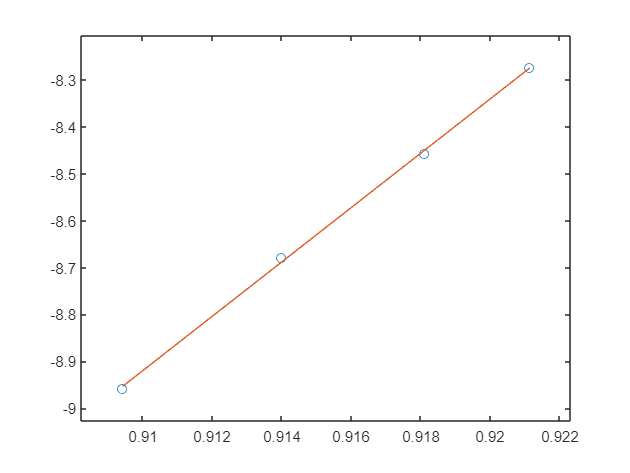

end

[alpha1, alpha1Std, alpha11, alpha11Std, n1, n1Std, ...
    Rs, RsStd, Is1, Is1Std, Rsh, RshStd] = deal(zeros(nStart, 1));
V_Trt = 0.02585;
for ii = 1:nStart
    Fit1_ = Fit1{ii};
    S = Fit1_.scale;
    alpha1(ii) = S*Fit1_.pfit(1);
    alpha1Std(ii) = S*Fit1_.pstd(1);
    temp(ii) = 300/(alpha1(ii) * V_Trt * N_IDEALITY_FACTOR)
    tempStd(ii) = sqrt(    temp(ii)^2 * ( (N_IDEALITY_FACTOR_STD/N_IDEALITY_FACTOR)^2 + (alpha1Std(ii)/alpha1(ii)^2)))
    Rs(ii) = -S*Fit1_.pfit(2)/alpha1(ii);


$$d\;R_S =d\;\left(\frac{p_2 }{\alpha \;}\right)=\frac{d\;p_{2\;} }{\alpha \;}+\frac{p_2 }{\alpha^2 }d\alpha =R_S \left(\frac{{d\;p}_2 }{p_2 }+\frac{d\alpha }{\alpha \;}\right)$$


    RsStd(ii) = sqrt( ...
        Rs(ii)^2 * ( ...
            (Fit1_.pstd(2)/Fit1_.pfit(2))^2 + (alpha1Std(ii)/alpha1(ii))^2  ...
        ));

    Fit2_ = Fit2{ii};
    S = Fit2_.scale;
    alpha11(ii) = S*Fit2_.pfit(1);    % Another value of alpha
    alpha11Std(ii) = S*Fit2_.pstd(1);
    Is1(ii) = exp(S*Fit2_.pfit(2));


$$d\;I_S \;=d\;\left(\exp \left(p_2 \right)\right)=\exp \left(p_2 \right)*d\;p_2 =I_S *{d\;p}_2$$


    Is1Std(ii) = Is1(ii)*S*Fit2_.pstd(2);
end

temp = 327.1993

tempStd = 18.6589

temp =   327.1993  268.5405


tempStd =    18.6589   11.3527


temp =   327.1993  268.5405  348.9706


tempStd =    18.6589   11.3527   17.7104


temp =   327.1993  268.5405  348.9706  445.3519


tempStd =    18.6589   11.3527   17.7104   53.9977


temp =   327.1993  268.5405  348.9706  445.3519  690.0692


tempStd =    18.6589   11.3527   17.7104   53.9977  121.1296


temp =   327.1993  268.5405  348.9706  445.3519  690.0692   95.7147


tempStd =    18.6589   11.3527   17.7104   53.9977  121.1296    1.7253


bestFit = struct('IDX_START_INITIAL', IDX_START_IN, ...
    'IDX_START_FINAL', IDX_START_FIN, ...
    'alpha1', alpha1, ...
    'alpha1Std', alpha1Std, ...
    'temp', temp, ...
    'tempStd', tempStd, ...
    'alpha11', alpha11, ...
    'alpha11Std', alpha11Std, ...
    'Rs', Rs, ...
    'RsStd', RsStd, ...
    'Is1', Is1, ...
    'Is1Std', Is1Std);
% To save also the RMSD values compile also next section
% save('D:\Profile\qse\Files\_EDMRoC pinSC\IV curve\IV curve chip\04_IV_curve_n2_maxb1.mat', "V", "I", "bestFit", "Fit1", "Fit2")

# Analysis of fit results

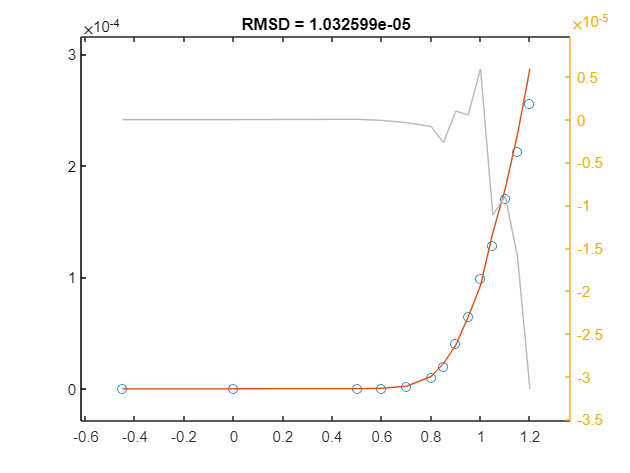

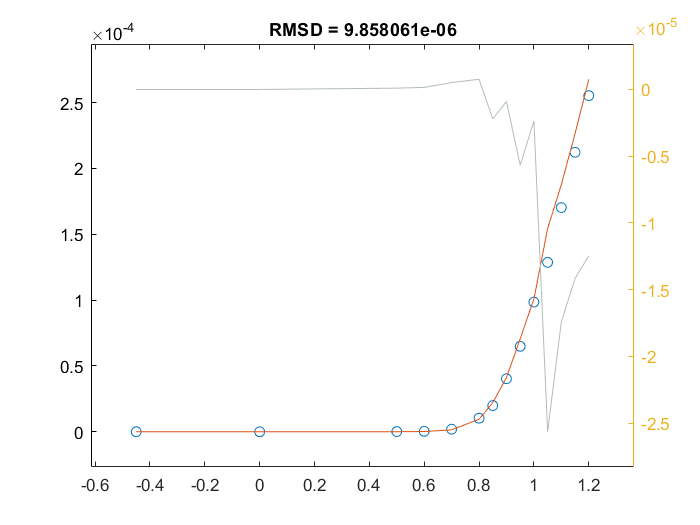

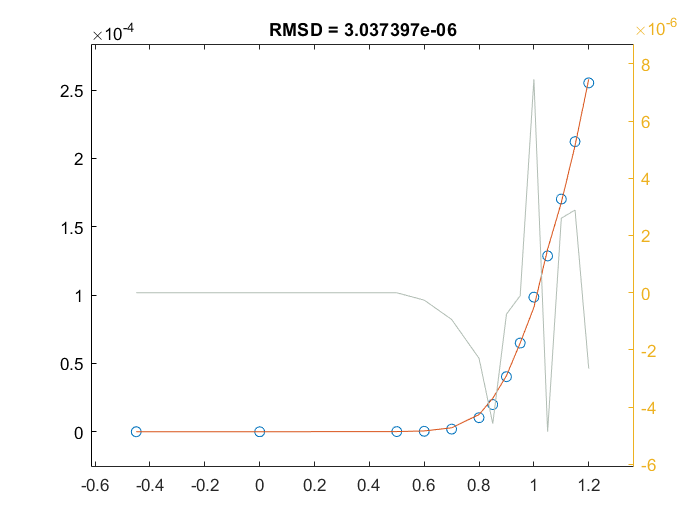

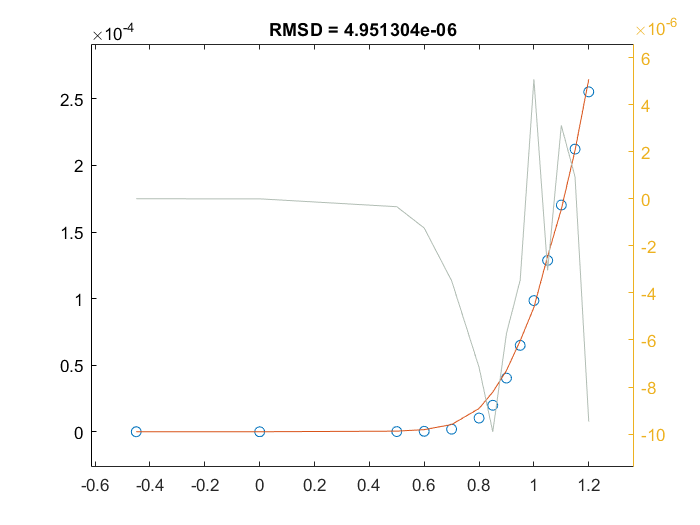

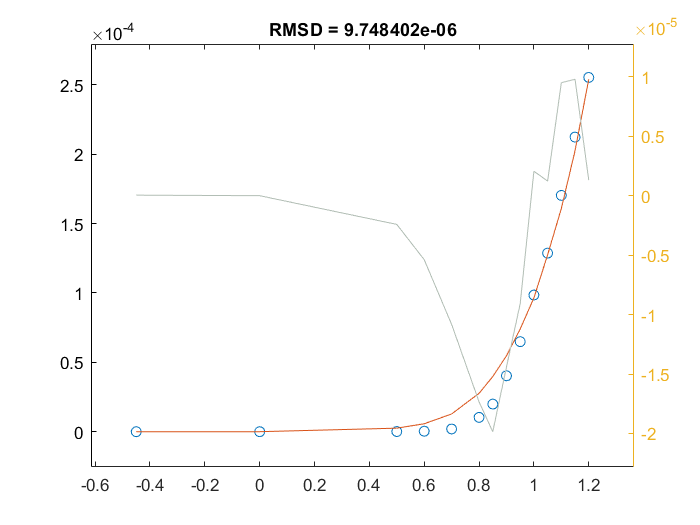

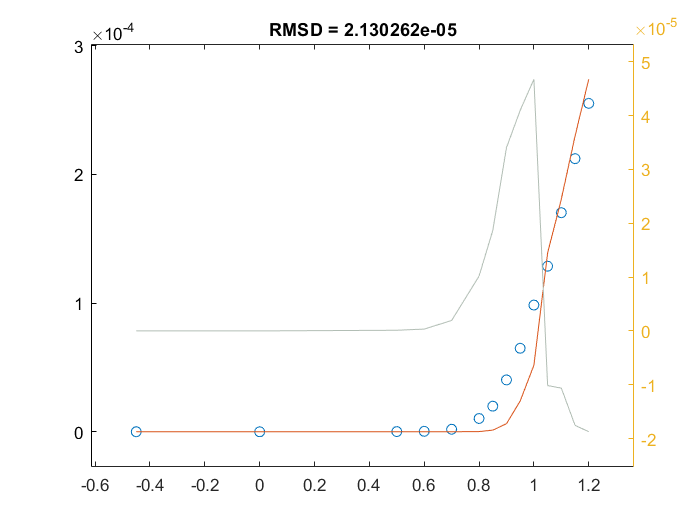

addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));
load('D:\Profile\qse\Files\_EDMRoC pinSC\IV curve\IV curve chip\04_IV_curve_n2_maxb1.mat');
load('GrayColorResiduals.mat');
Rmsd = ones(numel(Fit1), 1);
for ii = 1:numel(Fit1)
    Is_ = bestFit.Is1(ii);
    Rs_ = bestFit.Rs(ii);
    alpha_ = bestFit.alpha1(ii);
    Ifit_ = onediodemodel(V, I, [Is_, Rs_, 40e16, alpha_]);
    Fit1_ = Fit1{ii}; Fit2_ = Fit2{ii};
    Rmsd(ii) = rms(I-Ifit_);
    figure()
    tL = tiledlayout('flow');
    nexttile
    plot(V, I, 'o')
    hold on
    plot(V, Ifit_)
    xlim(setAxLim(V, 0.1))
    ylim(setAxLim(Ifit_, 0.1))
    yyaxis right
    plot(V, I - Ifit_, 'Color', GrayColorResiduals)
    ylim(setAxLim(I - Ifit_, 0.1))
    title(sprintf('RMSD = %d', Rmsd(ii)))
end

bestFit.Rmsd = Rmsd;
% save('D:\Profile\qse\Files\_EDMRoC pinSC\IV curve\IV curve chip\04_IV_curve_n2_maxb1.mat', "V", "I", "bestFit", "Fit1", "Fit2")

function Ifit = onediodemodel(V, I, p)
    % p = [I0, Rs, Rsh, alpha]
    Idiode = p(1)*(exp(p(4)*(V - I*p(2))) - 1);
    Ish = (V - I*p(2))/p(3);
    Ifit = Idiode + Ish;
end
function Ifit = twodiodemodel(V, I, p)
    % p = [I01, Rs, Rsh, alpha1, I02, alpha2]
    Idiode1 = p(1)*(exp(p(4)*(V - I*p(2))) - 1);
    Idiode2 = p(5)*(exp(p(6)*(V - I*p(2))) - 1);
    Ish = (V - I*p(2))/p(3);
    Ifit = Idiode1 + Idiode2 + Ish;
end